# Ce fichier est pour créer un terrain de golf sous forme d'une matrice

Notre terrain est de taille $0\ldotp 5\;X\;2\ldotp 5\;m^2$. Sa matrice correspondente est donc de taille 500 X 2500, c'est à dire chaque cas de la matrice représent $1\;{\mathrm{mm}}^2$ du terrain. De plus, les coordonnées x et y de terrain sont confondus avec les coordonnées des cas de la matrice. La coordonnée z de terrain est la valeur que prends chaque cas de la matrice.

On commencer par créer un terrain plat z=0

terrain = zeros(500,2500);

On souhaite que notre terrain a un pas d'hauteur qui est représenté par une fonction Heaviside. On remplace la discontinuité par un pôlynôme de degrée 5 qui assure la continuité au premier et second dérivée.

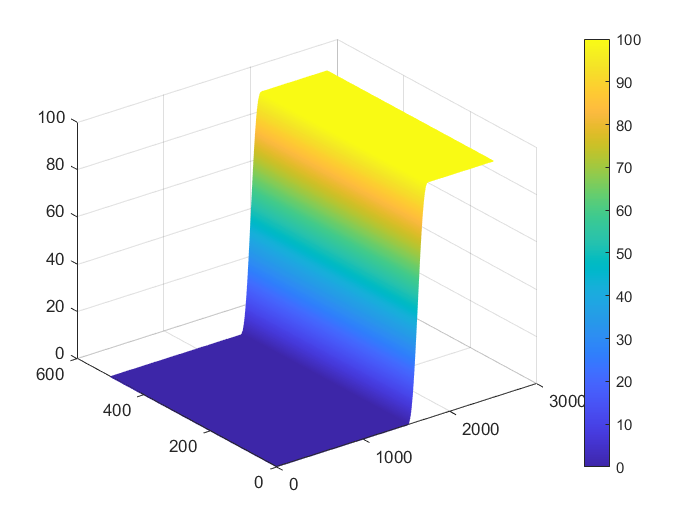

h = 100; %le pas d'hauteur vaut 10 cm
x0= 1500;%le pas commence à x0=1.5m
x1= 1750;%le pas temine à x1=1.75m
for x=x0:x1
    a = (x-x0)/(x1-x0);
    terrain(:,x)=h*a^3*(10-15*a+6*a^2);
end
terrain(:,x1:end)=h;
mesh(terrain);
colorbar;
saveas(gcf,'terrain.jpg');